# TRBGS experiments for different types of systems and sampling block sizes (Synthetic Data)

In this notebook, we are implementing tensor randomized Gauss Seidel with pseudoinverse computation (TRBGS) for solving A*X = B. We look at the cases of consistent, overdetermined and undertermined systems versus sampling block sizes.

% If needed, add a local path where the tproduct toolbox is located
addpath('.../tproduct toolbox 2.0 (transform)/')

% Define a destination folder for the figures
figsdest = '.../Synthetic_Data/Figs_TRBGS_and_TRBAGS';

% Set some universal (hyper)parameters
num_its = 100; % Number of iterations for all experiments
weights = ones(num_its);

% Set some figures options
line_styles = {'b-','r--','k-.','c:','g.','m-o'};
sep = 10;
legendStrings1 = '\mu = 1';
legendStrings2 = '\mu = 5';
legendStrings3 = '\mu = 10';

### **Case 1: Consistent, overdetermined tensor linear system**

First, we construct the tensors involved in the regression problem.

% Define tensor sizes
l = 10;
p = 30;
n = 20;
m = 30;

% Generate normally distributed pseudorandom tensors
A = randn(m,n,p);
X_true = randn(n,l,p);

% Generate consistent measurements
B = tprod(A,X_true);

% Compute the least-norm solution 
X_ln = tprod(tpinv(A),B);

Next, we implement tRBGS on this system for several block sizes

% Run some iterations of TRBGS
block_size = 1;
[rel_errs1,res_errs1] = TRBGS_err(A,B,zeros(n,l,p),num_its,X_true,X_ln,block_size);

block_size = 5;
[rel_errs5,res_errs5] = TRBGS_err(A,B,zeros(n,l,p),num_its,X_true,X_ln,block_size);

block_size = 10;
[rel_errs10,res_errs10] = TRBGS_err(A,B,zeros(n,l,p),num_its,X_true,X_ln,block_size);

Finally, we examine our results by plotting errors versus iterations.

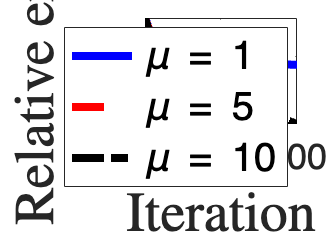

% Plot residual error vs iterations
figure();
semilogy(0:sep:num_its,rel_errs1(1:sep:num_its+1),line_styles{1},0:sep:num_its,rel_errs5(1:sep:num_its+1),line_styles{2},0:sep:num_its,rel_errs10(1:sep:num_its+1),line_styles{3},'LineWidth',4)
hold on
set(gca,'FontSize',18)
xlabel('Iteration','Interpreter','latex','FontSize',28) 
ylabel('Relative error','Interpreter','latex','FontSize',28) 
legend(legendStrings1,legendStrings2,legendStrings3,'FontSize',20) 
saveas(gca,fullfile(figsdest,'abs_err_vs_block_size_overdet_consistent.png'))
hold off

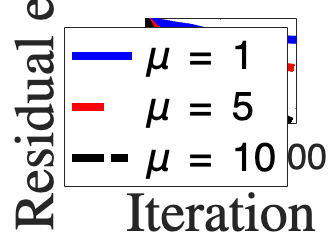

% Plot residual error vs iterations
figure();
semilogy(0:sep:num_its,res_errs1(1:sep:num_its+1),line_styles{1},0:sep:num_its,res_errs5(1:sep:num_its+1),line_styles{2},0:sep:num_its,res_errs10(1:sep:num_its+1),line_styles{3},'LineWidth',4)
hold on
set(gca,'FontSize',18)
xlabel('Iteration','Interpreter','latex','FontSize',28) 
ylabel('Residual error','Interpreter','latex','FontSize',28) 
legend(legendStrings1,legendStrings2,legendStrings3,'FontSize',20) 
saveas(gca,fullfile(figsdest,'res_err_vs_block_size_overdet_consistent.png'))
hold off

### **Case 2: Consistent, underdetermined tensor linear system**

First, we construct the tensors involved in the regression problem.

% Define tensor sizes
l = 20;
p = 10;
n = 30;
m = 10;

% Generate normally distributed pseudorandom tensors
A = randn(m,n,p);
X_true = randn(n,l,p);

% Generate consistent measurements
B = tprod(A,X_true);

% Compute the least-norm solution 
X_ln = tprod(tpinv(A),B);

Now, let's test the implementation of TRBGS on this system.

% Plot residual error vs iterations
block_size = 1;
[rel_errs1,res_errs1] = TRBGS_err(A,B,zeros(n,l,p),num_its,X_true,X_ln,block_size);

block_size = 5;
[rel_errs5,res_errs5] = TRBGS_err(A,B,zeros(n,l,p),num_its,X_true,X_ln,block_size);

block_size = 10;
[rel_errs10,res_errs10] = TRBGS_err(A,B,zeros(n,l,p),num_its,X_true,X_ln,block_size);

Finally, we examine our results by plotting errors versus iterations.

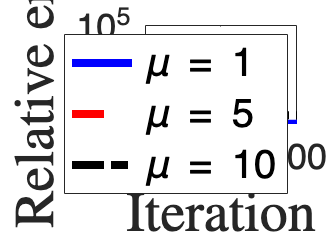

% Plot residual error vs iterations
figure();
semilogy(0:sep:num_its,rel_errs1(1:sep:num_its+1),line_styles{1},0:sep:num_its,rel_errs5(1:sep:num_its+1),line_styles{2},0:sep:num_its,rel_errs10(1:sep:num_its+1),line_styles{3},'LineWidth',4)
hold on
set(gca,'FontSize',18)
xlabel('Iteration','Interpreter','latex','FontSize',28) 
ylabel('Relative error','Interpreter','latex','FontSize',28) 
ylim([0,10^5])
legend(legendStrings1,legendStrings2,legendStrings3,'FontSize',20) 
saveas(gca,fullfile(figsdest,'abs_err_vs_block_size_underdet_consistent.png'))
hold off

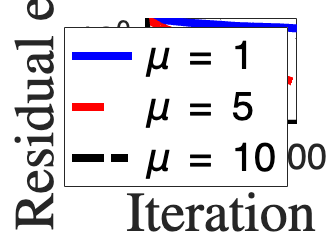

% Plot residual error vs iterations
figure();
semilogy(0:sep:num_its,res_errs1(1:sep:num_its+1),line_styles{1},0:sep:num_its,res_errs5(1:sep:num_its+1),line_styles{2},0:sep:num_its,res_errs10(1:sep:num_its+1),line_styles{3},'LineWidth',4)
hold on
set(gca,'FontSize',18)
xlabel('Iteration','Interpreter','latex','FontSize',28) 
ylabel('Residual error','Interpreter','latex','FontSize',28) 
legend(legendStrings1,legendStrings2,legendStrings3,'FontSize',20) 
saveas(gca,fullfile(figsdest,'res_err_vs_block_size_underdet_consistent.png'))
hold off

### **Case 3: Inconsistent, overdetermined tensor linear system**

First, we construct the tensors involved in the regression problem.

% Define tensor sizes
l = 10;
p = 30;
n = 20;
m = 30;

% Generate normally distributed pseudorandom tensors
A = randn(m,n,p);
X_true = randn(n,l,p);

% Generate component in col(A)^perp
Y_tild = randn(m,l,p);
X_tild = tprod(tpinv(A),Y_tild);
Y_perp = Y_tild - tprod(A,X_tild);

% Generate consistent and inconsistent measurements
B_true = tprod(A, X_true);
B = B_true + 0.005*Y_perp;

% Compute the least-norm solution 
X_ln = tprod(tpinv(A),B);

Now, let's test the implementation of TRBGS on this system

% Run some iterations of TRBGS
block_size = 1;
[rel_errs1,res_errs1] = TRBGS_err(A,B,zeros(n,l,p),num_its,X_true,X_ln,block_size);

block_size = 5;
[rel_errs5,res_errs5] = TRBGS_err(A,B,zeros(n,l,p),num_its,X_true,X_ln,block_size);

block_size = 10;
[rel_errs10,res_errs10] = TRBGS_err(A,B,zeros(n,l,p),num_its,X_true,X_ln,block_size);

Finally, we examine our results by plotting errors versus iterations.

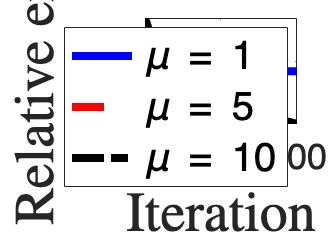

% Plot relative error vs iterations
figure();
semilogy(0:sep:num_its,rel_errs1(1:sep:num_its+1),line_styles{1},0:sep:num_its,rel_errs5(1:sep:num_its+1),line_styles{2},0:sep:num_its,rel_errs10(1:sep:num_its+1),line_styles{3},'LineWidth',4)
hold on
set(gca,'FontSize',18)
xlabel('Iteration','Interpreter','latex','FontSize',28) 
ylabel('Relative error','Interpreter','latex','FontSize',28) 
legend(legendStrings1,legendStrings2,legendStrings3,'FontSize',20) 
saveas(gca,fullfile(figsdest,'abs_err_vs_block_size_overdet_inconsistent.png'))
hold off

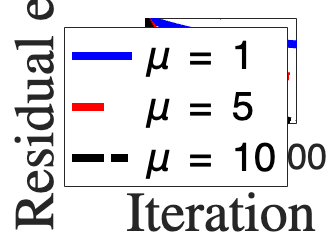

% Plot residual error vs iterations
figure();
semilogy(0:sep:num_its,res_errs1(1:sep:num_its+1),line_styles{1},0:sep:num_its,res_errs5(1:sep:num_its+1),line_styles{2},0:sep:num_its,res_errs10(1:sep:num_its+1),line_styles{3},'LineWidth',4)
hold on
set(gca,'FontSize',18)
xlabel('Iteration','Interpreter','latex','FontSize',28)  
ylabel('Residual error','Interpreter','latex','FontSize',28) 
legend(legendStrings1,legendStrings2,legendStrings3,'FontSize',20) 
saveas(gca,fullfile(figsdest,'res_err_vs_block_size_overdet_inconsistent.png'))
hold off